# Training Unit 6: Automatic Code Generation

Fink Lucas / Teichtmeister Marcus, 05.11.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Generating a Fibonacci Number Generator

Here you can define, which Fibonacci Number should be calculated:

n = 8;

If n exceeds the value 38 (7.18s) the computation time required will be above 10s (12.68s for 39) on the device used.

tic
nthFiboNum = fibonacciCalculation(n)

nthFiboNum =     21.0000e+000

toc

Elapsed time is 0.003780 seconds.


fprintf('\n--- Test for Argument Validation ---\n');


--- Test for Argument Validation ---



% Testfälle
test_cases = {-1; 'a'; [1, 2]; [2, 1]; 5i; 3.41; "Hello Fibonacci."};

% Iteration durch die Testfälle
for k = 1:size(test_cases, 1)
    n_input = test_cases{k, 1};

    try
        fibonacciCalculation(n_input);
    catch ME
        fprintf('Test successful #%d %s\n', k, ME.message);
    end
end

Test successful #1 Invalid argument at position 1. Value must be nonnegative.
Test successful #2 Invalid argument at position 1. Value must be numeric.
Test successful #3 Invalid argument at position 1. Value must be a scalar.
Test successful #4 Invalid argument at position 1. Value must be a scalar.
Test successful #5 Invalid argument at position 1. Value must be real.
Test successful #6 Invalid argument at position 1. Value must be integer.
Test successful #7 Invalid argument at position 1. Value must be numeric.


clearvars

## Generating a Matlab executable function from your Fibonacci function

n = 12;

The MEX-function (6.55s for n=43 and 10.89s for n=44) is considerably faster than the MATLAB-function (7.18s for n=38)

tic
nthFiboNum = fibonacciCalculation_mex(n)

nthFiboNum =    144.0000e+000

toc

Elapsed time is 0.002001 seconds.


% Testfälle
test_cases = {-1; 'a'; [1, 2]; [2, 1]; 5i; 3.41; "Hello Fibonacci."};

% Iteration durch die Testfälle
for k = 1:size(test_cases, 1)
    n_input = test_cases{k, 1};

    try
        fibonacciCalculation_mex(n_input);
    catch ME
        fprintf('Test successful #%d %s\n', k, ME.message);
    end
end

Test successful #1 Value must be nonnegative.
Test successful #2 Incorrect class for expression 'n': expected 'double' but found 'char'.
Test successful #3 Incorrect size for expression 'n': expected [1x1] but found [1x2].
Test successful #4 Incorrect size for expression 'n': expected [1x1] but found [1x2].
Test successful #5 MATLAB expression 'n' is not of the correct complexness.
Test successful #6 Value must be integer.
Test successful #7 Incorrect class for expression 'n': expected 'double' but found 'string'.


clearvars

## Function Performance Testing

n = 8; 

num_runs = 100000; 

matlab_times = zeros(1, num_runs);
mex_times = zeros(1, num_runs);

%% 1. Performance-Test: MATLAB-Funktion (fibonacciCalculation.m)
for i = 1:num_runs
    tic;
    fibonacciCalculation_mex(n); 
    matlab_times(i) = toc;
end

%% 2. Performance-Test: MEX-Funktion (fibonacciCalculation_mex.mexw64)
for i = 1:num_runs
    tic; 
    fibonacciCalculation_mex(n); 
    mex_times(i) = toc;
end

std_matlab = std(matlab_times)

std_matlab =      1.9383e-006

std_mex = std(mex_times)

std_mex =      1.4054e-006

% --- Statistical Evaluation ---
mean_matlab_time = mean(matlab_times);
mean_mex_time = mean(mex_times);

% Calculate time saving in percent
time_saving_percent = ((mean_matlab_time - mean_mex_time) / mean_matlab_time) * 100;
disp(['Mean MATLAB time: ', num2str(mean_matlab_time * 1e6), 'us']);

Mean MATLAB time: 2.8933us


disp(['Mean MEX time:    ', num2str(mean_mex_time * 1e6), 'us']);

Mean MEX time:    2.8731us


disp(['Time Saving (using MEX): ', num2str(time_saving_percent), '%']);

Time Saving (using MEX): 0.69841%


figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(1,2);

% --- Visualization (Bar Chart) --- 
nexttile
bar_data = [mean_matlab_time, mean_mex_time] * 1e6; 
bar(bar_data);
set(gca, 'XTickLabel', {'MATLAB Function', 'MEX Function'});
ylabel('Mean Execution Time in us'); 
title(['Mean Performance Comparison for Fibonacci(', num2str(n), ')']);
grid on;

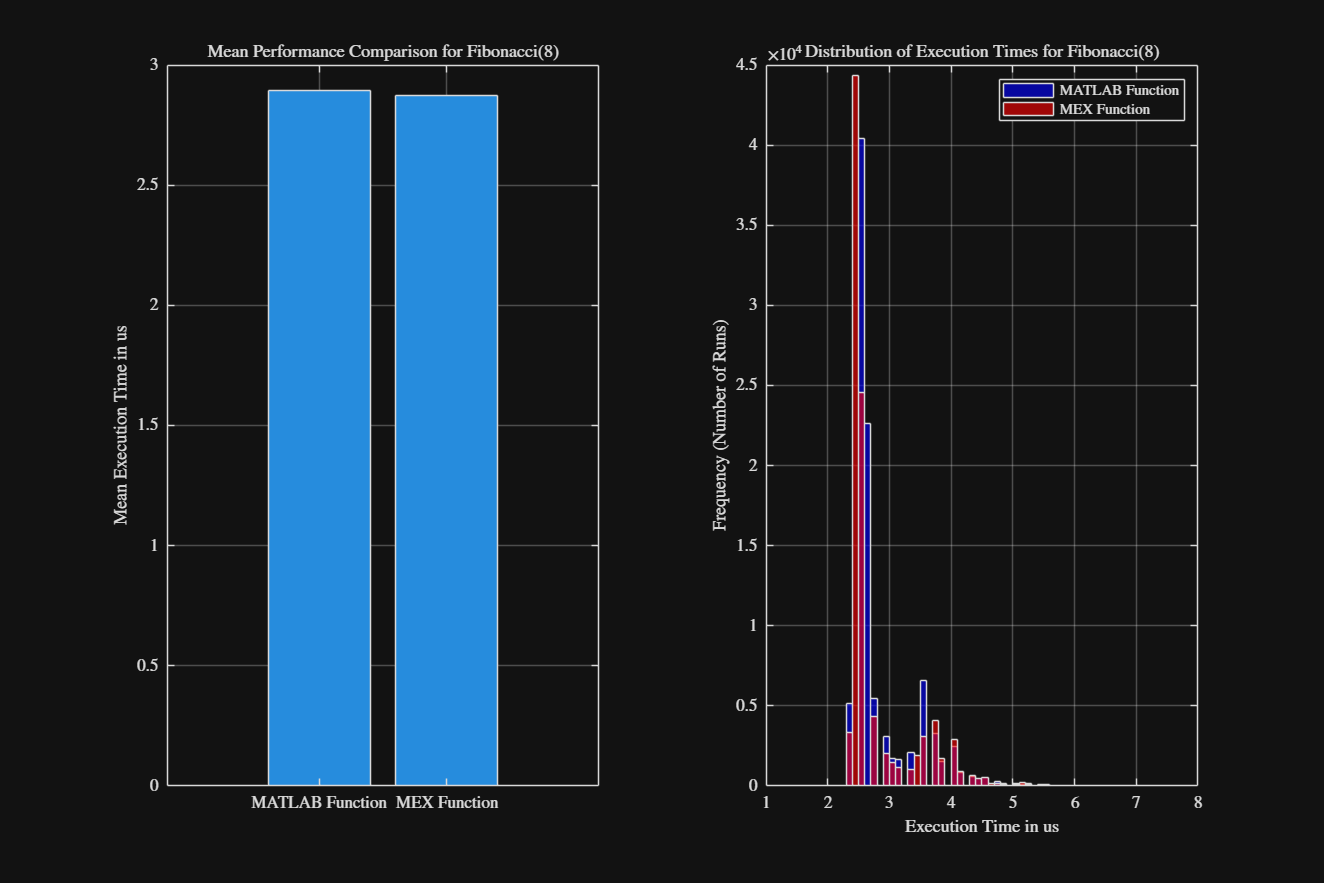

% --- Visualization (Histogram) ---
nexttile
h1 = histogram(matlab_times * 1e6, 'FaceColor', 'b', 'BinWidth', 0.1); 
hold on;
h2 = histogram(mex_times * 1e6, 'FaceColor', 'r', 'BinWidth', 0.1);
legend('MATLAB Function', 'MEX Function');
xlabel('Execution Time in us');
ylabel('Frequency (Number of Runs)');
title(['Distribution of Execution Times for Fibonacci(', num2str(n), ')']);
xlim([1, 8])
hold off;
grid on;

% --- Test Without Pre-allocation ---
disp(' ');

disp('Testing the effect of NO Pre-allocation...');

Testing the effect of NO Pre-allocation...


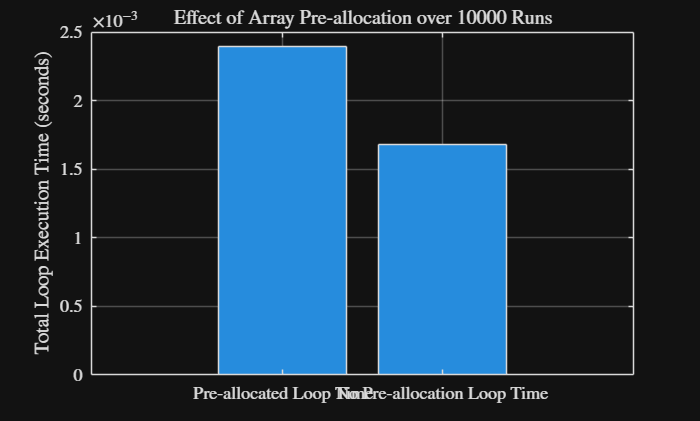


% Start a new loop without pre-allocating the array
matlab_times_no_prealloc = []; % Start with an empty array
num_runs_prealloc_test = 10000; % Use a high number of runs to see the effect

tic; % Start a single overall timer for the entire loop
for i = 1:num_runs_prealloc_test
    tic;
    F_matlab = fibonacciCalculation(n);
    % Dynamically grow the array in each iteration (INEFFICIENT!)
    matlab_times_no_prealloc(i) = toc; 
end
time_no_prealloc = toc;
mean_matlab_time_no_prealloc = mean(matlab_times_no_prealloc);

% Re-run the pre-allocated test for a fair comparison (using the same num_runs)
matlab_times_prealloc = zeros(1, num_runs_prealloc_test);
tic; % Start a single overall timer for the entire loop
for i = 1:num_runs_prealloc_test
    tic;
    F_matlab = fibonacciCalculation(n);
    matlab_times_prealloc(i) = toc;
end
time_prealloc = toc;
mean_matlab_time_prealloc = mean(matlab_times_prealloc);


% --- Plotting the Effect of Pre-allocation ---
figure;
bar([time_prealloc, time_no_prealloc]);
set(gca, 'XTickLabel', {'Pre-allocated Loop Time', 'No Pre-allocation Loop Time'});
ylabel('Total Loop Execution Time (seconds)');
title(['Effect of Array Pre-allocation over ', num2str(num_runs_prealloc_test), ' Runs']);
grid on;

disp(['Total Time (Pre-allocated): ', num2str(time_prealloc), ' seconds']);

Total Time (Pre-allocated): 0.0023967 seconds


disp(['Total Time (No Pre-allocation): ', num2str(time_no_prealloc), ' seconds']);

Total Time (No Pre-allocation): 0.0016806 seconds
